# **Experiment: Advanced Computation for Energy Engineering**

## **Name: Abisoye Akinloye**

## **Particle Swarm Optimization (PSO)**

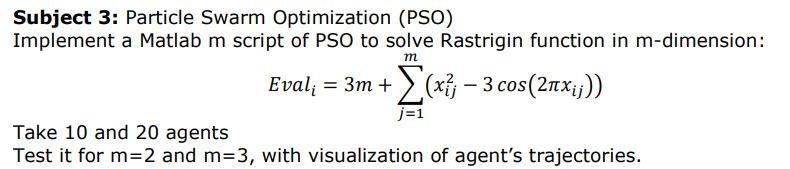

## Rastrigin Function

Create a `m script` for the rastrigin function

**For a Rastrigin function:**

- The Rastrigin function has several local minima.

- It is highly multimodal, but locations of the minima are regularly distributed.

- The function is usually evaluated on the hypercube $x_i \in \left\lbrack -5\ldotp 12,5\ldotp 12\right\rbrack$, for all $i=1,\ldotp \ldotp \ldotp ,m$

**Reference:** [https://www.sfu.ca/~ssurjano/rastr.html](https://www.sfu.ca/~ssurjano/rastr.html)

## PSO Algorithm

### **General steps**

- Initialize the algorithm parameter ($\omega \;,c_1 ,c_2$). Algorithm parameter to be explained later

- Initialize the population (swarm of particles) with random position $x$ and velocity $v$ (v can be otherwise initialized as zero)

- Evaluate the fitness $f$ of each particle using the fitness function

- Update the particle's pbest and gbest using equation (a) and (b), respectively.

- Generate random numbers $r_{1\;} \&\;r_{2\;}$

- Update the velocity of each particle using equation (c) as shown below

- Update the position of each particle using equation (d) as shown below

- Loop through **step 3 to 7** until a stopping criteria is met. Stopping criteria can be a user-defined number of iterations.

### Equations

- $P_{\left(i,\textrm{lb}\right)}^{\left(t\right)}$ is the personal best position of $i-\textrm{th}$ particle in $t$ generation. Assume minimization problem

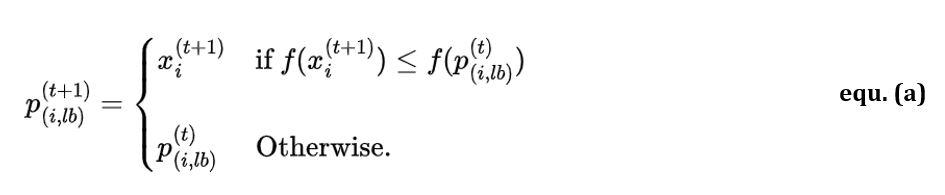

- $P_{\textrm{gb}}^{\left(t\right)}$ is the global best position in $t$ generation. It is the minimum fitness which is calculated as:

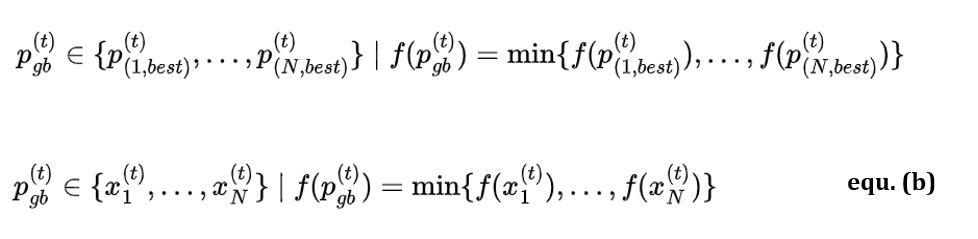

- Velocity and position update

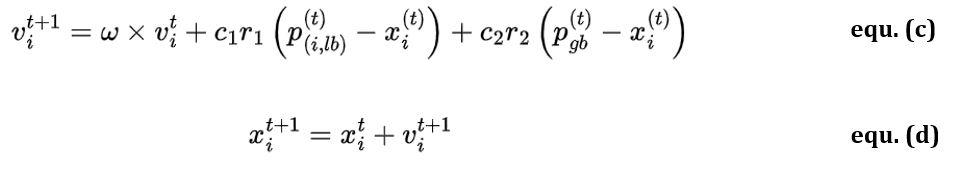

Where 

- N is the number of particles in the swarm

- $\textrm{lb}$ is local (personal) best, $\textrm{gb}$ is the global best

- $i$ is the number of iteration

- ω is the inertia weight

- $c_1 \;\&\;c_{2\;}$ are the acceleration coefficients

- $r_{1\;} \&\;r_{2\;}$ are random numbers between 0 and 1 and are generated in each iteration for each dimension, and not for each particle.

- pbest is the best position achieved by the particle.

- gbest is the best position achieved by the whole swarm.

- T is the number of iteration

### Flowchart of PSO

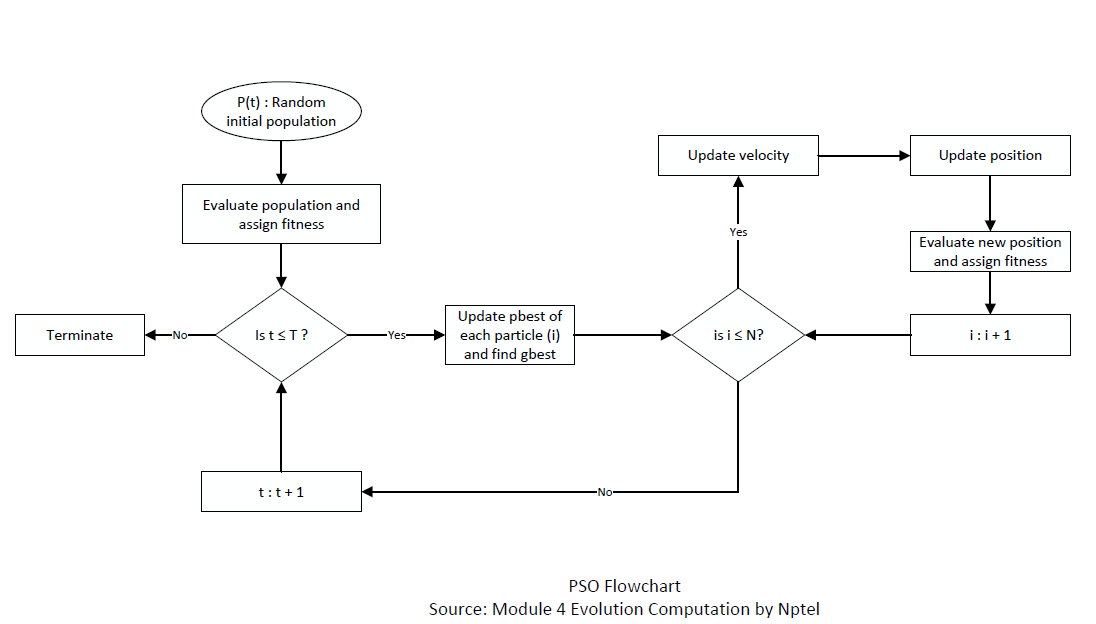

**Bibliography: **

- [https://www.udemy.com/course/bio-inspired-artificial-intelligence-algorithms-for-optimization](https://www.udemy.com/course/bio-inspired-artificial-intelligence-algorithms-for-optimization)

- [https://www.oreilly.com/library/view/optimization-algorithms/9781633438835/](https://www.oreilly.com/library/view/optimization-algorithms/9781633438835/)

- [https://drive.google.com/file/d/146EpYC6qX5Rk-GEGD6oRtH5TD8t9SmJK/view](https://drive.google.com/file/d/146EpYC6qX5Rk-GEGD6oRtH5TD8t9SmJK/view)

- [https://archive.nptel.ac.in/courses/112/103/112103301/](https://archive.nptel.ac.in/courses/112/103/112103301/)

- [https://www.researchgate.net/publication/379603938_Particle_Swarm_and_Genetic_Algorithms_applied_to_the_identification_of_Induction_Machine_Parameters](https://www.researchgate.net/publication/379603938_Particle_Swarm_and_Genetic_Algorithms_applied_to_the_identification_of_Induction_Machine_Parameters)

## Code Implementation

#### User defined parameters

%% User defined parameters
m = 2;                  % dimensionality (search space) for m = 2 or m = 3
n_particles = 10;       % numbers of particles (agents) set for 10 or 20
max_iter = 100;         % maximum iteration which is the stopping criteria
fprintf("User parameter for simulation defined!")

User parameter for simulation defined!

#### PSO hyperparameters

%% PSO hyperperameters
w = 0.7;                      % inertia weight
c1 = 1.4;                     % cognitive (personal) coefficient
c2 = 1.2;                     % social coefficient

% for rastrigin problems, the search space boundaries is 
% commonly [-5.12 5.12]
min_x = -5.12;                % minimum search space boundary
max_x = 5.12;                 % maximum search space boundary

fprintf("PSO hyperparameter for simulation defined!")

PSO hyperparameter for simulation defined!

- **Inertia component (**$\omega$**):** The first part of the velocity update equation represents the influence of a particle’s inertia, taking into account that a particle (like a fish in a school or a bird in a flock) cannot abruptly change its direction. Large values of ω encourage **exploration**, while small values promote **exploitation**, allowing the cognitive and social components to exert greater control. A widely adopted value for **ω is 0.792.**

- **Cognitive component: **The second part of the equation (c), referred to as the cognitive component, represents the particle’s attraction toward its personal best position, or individual proximity (i-proximity). The cognitive component encourages particles to explore the areas around their personal best positions, allowing them to fine-tune their search in promising regions. Setting c1 to 0 reduces the PSO algorithm to a social-only or selfless PSO model. Hence, particles are solely attracted to the group best and ignore their personal bests. This leads to an emphasis on global exploration based on the swarm’s collective knowledge.

- **Social component:** The third part of the velocity update equation is the social component, which represents the particle’s attraction to the swarm’s collective knowledge or group proximity (g-proximity). The social component fosters collaboration among particles, helping them converge toward an optimal solution more effectively. Setting c2 to 0 results in a cognition-only model, where particles act as independent hill climbers, relying only on their personal bests.

- **Note:** In many applications, c1 and c2 are set to **1.49.** Although there is no theoretical justification for this specific value, it has been empirically found to work well in various optimization problems. Generally, the **sum of c1 and c2 should be less than or equal to 4 **to maintain the algorithm’s stability and convergence properties.

#### **Motion Visualization**

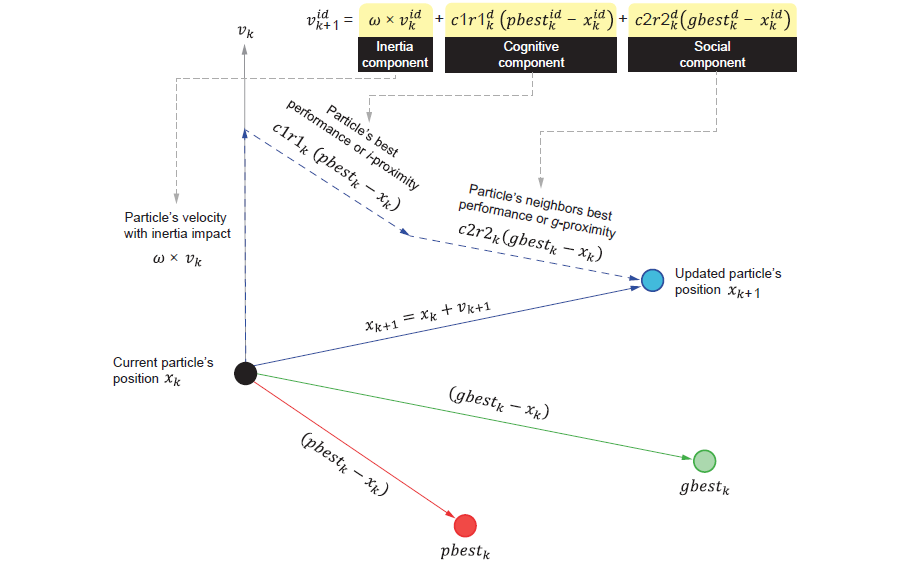

#### Initialize Swarm

%% Initialize the Swarm

% initialize the position with random value with [min_x max_x]
x = min_x + (max_x - min_x) .* rand(n_particles, m);

% initialize the velocity to zero
v = zeros(n_particles, m);

% initialize the fitness funtion
fitness = zeros(n_particles, 1);

for i = 1 : length(x)
    fitness(i) = rastrigin(x(i,:));
end

% personal best
p_best_pose = x;                % personal best position
p_best_val = fitness;           % personal best value

% global best
% the global best value is the minimum fitnes
[gbest_val, gbest_idx] = min(fitness);      % find the index of the minimum fitness
% the index of minimum fitness is the global best position

Swarm initialization done!

gbest_pose = x(gbest_idx,:);                 % global best position

fprintf("Swarm initialization done!")

#### **Create Figure Template**

- **Mesh grid:** [https://www.mathworks.com/help/matlab/ref/meshgrid.html](https://www.mathworks.com/help/matlab/ref/meshgrid.html)

- **Linspace:** [https://www.mathworks.com/help/matlab/ref/double.linspace.html](https://www.mathworks.com/help/matlab/ref/double.linspace.html)

%% Figure template
if m == 2
    figure('Name','PSO Rastrigin 2D','NumberTitle','off');
elseif m == 3
    figure('Name','PSO Rastrigin 3D','NumberTitle','off');
end

% figure template for precomputing grid for countor and surf
[X, Y] = meshgrid(linspace(min_x, max_x, 100), linspace(min_x, max_x, 100));
Z = zeros(size(X));
for i = 1:size(X,1)
    for j = 1:size(X,2)
        Z(i,j) = rastrigin([X(i,j), Y(i,j)]);
    end
end

Figure template for the plot created!


fprintf("Figure template for the plot created!")

#### Main PSO Loop

Iteration 1  	| Global Best Value = 5.159142
Iteration 2  	| Global Best Value = 2.398222
Iteration 3  	| Global Best Value = 1.204072
Iteration 4  	| Global Best Value = 1.204072
Iteration 5  	| Global Best Value = 1.204072
Iteration 6  	| Global Best Value = 1.204072
Iteration 7  	| Global Best Value = 1.204072
Iteration 8  	| Global Best Value = 1.204072
Iteration 9  	| Global Best Value = 1.204072
Iteration 10  	| Global Best Value = 1.204072
Iteration 11  	| Global Best Value = 1.204072
Iteration 12  	| Global Best Value = 0.201617
Iteration 13  	| Global Best Value = 0.201617
Iteration 14  	| Global Best Value = 0.201617
Iteration 15  	| Global Best Value = 0.014447
Iteration 16  	| Global Best Value = 0.014447
Iteration 17  	| Global Best Value = 0.014447
Iteration 18  	| Global Best Value = 0.014447
Iteration 19  	| Global Best Value = 0.014447
Iteration 20  	| Global Best Value = 0.014447
Iteration 21  	| Global Best Value = 0.014447
Iteration 22  	| Global Best Value = 0.0144

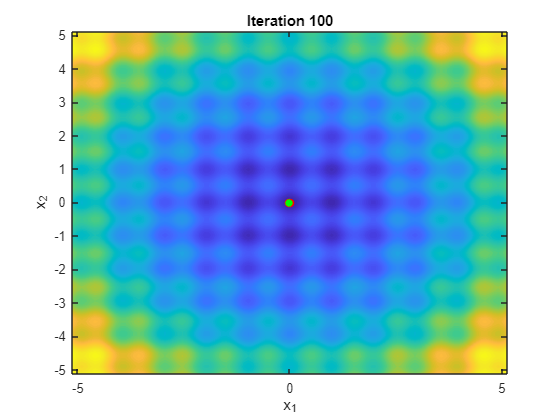

for iter = 1 : max_iter
    % update velocities and positions of the particles (agents)
    for i = 1 : n_particles
        % random coefficients for behavior ranging from 0 - 1
        r1 = rand(); r2 = rand();

        % velocity update
        v(i,:) = w*v(i,:) + c1*r1*(p_best_pose(i,:) - x(i,:)) + c2*r2*(gbest_pose - x(i,:));

        % update the position
        x(i,:) = x(i,:) + v(i,:);

        % boundary conditions to make sure position isn't 
        % beyound [min_x max_x] limit
        for d = 1:2
            if x(i, d) > max_x
                x(i, d) = max_x;
            elseif x(i, d) < min_x
                x(i, d) = min_x;
            end
        end
    end

    % evaluate fitness after updating positions
    for i = 1 : n_particles
        fitness(i) = rastrigin(x(i,:));

        % update personal best
        if fitness(i) < p_best_val(i)
            p_best_val(i) = fitness(i);
            p_best_pose(i,:) = x(i,:);
        end
    end

    % update global best
    [current_best, current_best_idx] = min(p_best_val);
    if current_best < gbest_val
        gbest_val = current_best;
        gbest_pose = p_best_pose(current_best_idx, :);
    end

    % display iteration info
    fprintf('Iteration %d  \t| Global Best Value = %f\n', iter, gbest_val);

    % plot the graph
    if m == 2
        clf;
        contourf(X,Y,Z,80, 'LineColor', 'none'); hold on;
        plot(p_best_pose(:,1), p_best_pose(:,2), 'ro', 'MarkerFaceColor','r');
        plot(gbest_pose(:,1), gbest_pose(:,2), 'ro', 'MarkerFaceColor','g');
        title(['Iteration ' num2str(iter)]);
        xlabel('x_1'); ylabel('x_2');
        axis([min_x max_x min_x max_x]);
        drawnow; % for the plot animation

    elseif (m == 3)
        clf; % clear figure
        surf(X, Y, Z, 'EdgeColor','none');
        colormap('jet');
        hold on;
        view(45, 45); % view angle
    
        % evaluate Rastrigin at each particle to show their 'height'
        zPos = arrayfun(@(row) rastrigin(p_best_pose(row,:)), 1:size(p_best_pose,1));
        scatter3(p_best_pose(:,1), p_best_pose(:,2), zPos, 40, 'r', 'filled');
        title(['Iteration ' num2str(iter)]);
        xlabel('x_1'); ylabel('x_2'); zlabel('Function Value');
        drawnow; % plot animation
    end
end

**Note: **

- `arrayfun:` [https://www.mathworks.com/help/matlab/ref/arrayfun.html](https://www.mathworks.com/help/matlab/ref/arrayfun.html)

- It is used with an anonymous function: [https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html)

- This is done to avoid writing` function `m script and the output is turned to an array.

#### Final Result

%% final result

fprintf('Best value found: %f\n', gbest_val);

Best value found: 0.000000


if m == 2
    fprintf('Best position found: [%f, %f]\n', gbest_pose(1), gbest_pose(2));

Best position found: [0.000000, 0.000000]


elseif m == 3
    fprintf('Best position found: [%f, %f, %f]\n', gbest_pose(1), gbest_pose(2), gbest_pose(3));
end

## PSO Simulation Video

**Click here: **[**https://drive.google.com/drive/folders/16-piIizYJNG8Ki1unexyFoG23p-lYtej?usp=sharing**](https://drive.google.com/drive/folders/16-piIizYJNG8Ki1unexyFoG23p-lYtej?usp=sharing)

## Source Code

- Copy the code in the code box below and name the m script file as `rastrigin.m`

- Copy the code below and name the m script file as `PSO_Rastrigin.m`

- Save both files in the same folder and run this command in the command window

- Source code can be found on the Github page: [https://github.com/Abisoyesam/Computation-for-Energy/tree/main/PSO](https://github.com/Abisoyesam/Computation-for-Energy/tree/main/PSO)